clear all
data=readtable("C:\Users\thoma\Downloads\book1.xlsx")

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

           NaT    3320.3               6843.8           
    28/02/2019    3298.3               6798.3           
    27/02/2019    3282.8               6766.4           
    26/02/2019    3289.3               6779.9           
    25/02/2019      3280               6760.7           
    22/02/2019    3270.6               6741.2           
    21/02/2019    3263.7               6727.1           
    20/02/2019    3259.5               6718.4           
    19/02/2019    3239.4                 6677           
    18/02/2019    3244.8               6688.1           
    15/02/2019    3241.3               6680.8           
    14/02/2019    3182.7                 6560           
    13/02/2019    3202.4                 6599           
    12/02/2019    3190


data=flipud(data)

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

    31/12/1986    900.82               900.82           
    01/01/1987    900.82               900.82           
    02/01/1987    891.78               891.78           
    05/01/1987    898.33               898.33           
    06/01/1987    902.32               902.32           
    07/01/1987    899.15               899.15           
    08/01/1987    887.37               887.37           
    09/01/1987    868.31               868.31           
    12/01/1987    879.41               879.41           
    13/01/1987    872.74               872.74           
    14/01/1987    876.39               876.39           
    15/01/1987    884.37               884.37           
    16/01/1987    883.78               883.78           
    19/01/1987    876.

dates=datetime(data.Date,'Convertfrom','excel');
logreturn=[nan;diff(log(data.PX_LAST))]*100

logreturn =        NaN
         0
   -1.0086
    0.7318
    0.4432
   -0.3519
   -1.3188
   -2.1713
    1.2702
   -0.7614



logreturn=[nan;100*diff(log(data.PX_LAST))]

logreturn =        NaN
         0
   -1.0086
    0.7318
    0.4432
   -0.3519
   -1.3188
   -2.1713
    1.2702
   -0.7614


initialvaerdier = [0.001,1,0.05,0.9,0.0001]

initialvaerdier =     0.0010    1.0000    0.0500    0.9000    0.0001


Ovenfor=[100*nanmean(logreturn) inf 1 1 1]

Ovenfor =     1.5730       Inf    1.0000    1.0000    1.0000


any(logreturn>5)

ans = logical
   1


Nedenfor=[-nanmean(logreturn) 0 0 0 0]

Nedenfor =    -0.0157         0         0         0         0


T=size(logreturn,1)

T = 8294

A=[0 0 1 1 0];
b=1;
w = .05*.9.^(0:T-2);
backCast= w*logreturn(2:end).^2;
backCast=0.01

backCast = 0.0100

options = optimset('fmincon');
options.Display = 'iter';
options.Algorithm = 'sqp';
options.Functiontolerance=1/100000000000;
options.TolCon=1/100000000000;
 estimates = fmincon(@GARCH_likelihood,initialvaerdier,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:1500),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    1.826901e+03     0.000e+00     1.000e+00     0.000e+00     6.718e+03  
    1          14    1.168859e+03     0.000e+00     4.900e-01     1.126e+00     3.979e+03  
    2          22    1.121936e+03     0.000e+00     4.900e-01     7.807e-01     1.813e+03  
    3          29    7.419474e+02     0.000e+00     7.000e-01     8.823e-01     2.508e+03  
    4          38    7.180699e+02     0.000e+00     3.430e-01     7.248e-01     1.103e+03  
    5          45    6.928127e+02     0.000e+00     7.000e-01     1.127e+00     8.498e+02  
    6          52    6.429116e+02     0.000e+00     7.000e-01     3.074e-01     3.878e+03  
    7          63    6.383918e+02     0.000e+00     1.681e-01     2.295e-01     2.910e+03  
    8          78    6.023871e+02     0.000e+00     4.035e-02     1.151e-01     6.

 initialvaerdier2=[estimates]

initialvaerdier2 =     0.0165    0.1439    0.1830    0.6107    0.6131


 [estimates2,fval,exitflag,output,lambda,gradient,hessian] = fmincon(@GARCH_likelihood,initialvaerdier2,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    4.931433e+03     0.000e+00     1.000e+00     0.000e+00     3.815e+03  
    1          41    4.917565e+03     0.000e+00     3.220e-05     6.780e-02     1.128e+03  
    2          54    4.909966e+03     0.000e+00     8.235e-02     9.254e-02     9.266e+02  
    3          61    4.789796e+03     0.000e+00     7.000e-01     2.896e-01     6.536e+03  
    4          69    4.723026e+03     0.000e+00     4.900e-01     2.405e-01     4.794e+03  
    5          83    4.705688e+03     0.000e+00     5.765e-02     3.268e-02     3.672e+03  
    6         101    4.705118e+03     0.000e+00     1.384e-02     2.777e-02     3.517e+03  
    7         115    4.696926e+03     0.000e+00     5.765e-02     7.351e-02     1.201e+03  
    8         126    4.685731e+03     0.000e+00     1.681e-01     9.873e-02     1.


 % mdl=arima(data,1,0)
% es
% 
fval

fval = 4.6592e+03

exitflag

exitflag = 2

output

output = struct with fields:
         iterations: 25
          funcCount: 262
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-11.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   7.26e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-11 (selected)'
    constrviolation: 0
           stepsize: 7.4489e-07
       lssteplength: 0.0576
      firstorderopt

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


gradient

gradient =    -0.0065
   -0.0038
   -0.0132
   -0.0052
   -0.0041


hessian

hessian = 	1.0e+06 *

    0.1233    0.1475    0.2791    0.1326    0.0484
    0.1475    0.7526    0.7478    0.5366    0.0887
    0.2791    0.7478    1.4238    0.8210    0.1664
    0.1326    0.5366    0.8210    0.5317    0.0890
    0.0484    0.0887    0.1664    0.0890    0.0232


eig(hessian)

ans = 	1.0e+06 *

    0.0001
    0.0099
    0.0850
    0.2739
    2.4856


any(eig(hessian)<=0)

ans = logical
   0


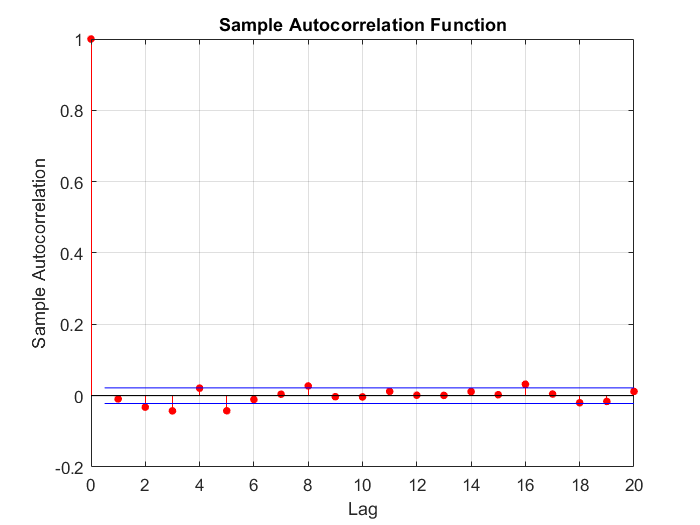

[ll,lls,h,fejlled]=GARCH_likelihood(estimates2,logreturn(2:end),backCast);
autocorr(logreturn(2:end))

[acf,lags,bounds]=autocorr(logreturn(2:end))

acf =     1.0000
   -0.0092
   -0.0323
   -0.0426
    0.0211
   -0.0423
   -0.0109
    0.0041
    0.0272
   -0.0029


lags =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


bounds =     0.0220
   -0.0220


% lmctest(h)
% logreturn=logreturn/100
% h=h/10000
h

h =     0.0100
    0.0416
    0.1835
    0.1952
    0.1961
    0.2431
    0.4880
    1.0736
    0.9408
    1.0365


standardfejl=fejlled./sqrt(h)

standardfejl =    -0.0809
   -5.0098
    1.6779
    0.9734
   -0.8242
   -2.7010
   -3.1270
    1.2133
   -0.7985
    0.3971


[h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)

h = logical
   0


pValue = 0.1859

stat = 7.5020

cValue = 11.0705

[h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

h = logical
   0


pValue = 0.8718

stat = 1.2381

cValue = 9.4877

mean(standardfejl)

ans = 0.0032

mean(standardfejl.^2)

ans = 1.0012

mean(standardfejl.^3)

ans = -0.5461

mean(standardfejl.^4)

ans = 7.4093

[h,p,jbstat,critval]=jbtest(standardfejl)

h = 1

p = 1.0000e-03

jbstat = 7.1108e+03

critval = 5.9853

% [ts,pv]=ljungbox(z,12)
% [ts,pv]=lmtest(z,12,8294);


% [h,pvalue,stat,cvalue]=archtest(z)
% z=(logreturn(2:end)-mean(logreturn(2:end)))./sqrt(var(logreturn(2:end)))
% [h,p,jbstat,critval]=jbtest(z)
% 
% plot(z)
% [ts,pv]=ljungbox(z,12)
% [ts,pv]=lmtest(z,12,8294);
% zminus=-z.*1.96
% zplus=z.*1.96
% plot(dates(2:end),zminus,'blue',dates(2:end),zplus,'blue',dates(2:end),z,'red')
% 
% 
% [h,pvalue,stat,cvalue]=archtest(z)
estimates=estimates'

estimates =     0.0165
    0.1439
    0.1830
    0.6107
    0.6131


 



h

h = 1

lls

lls =    -2.2993
   10.9433
    0.5599
   -0.3430
   -0.4747
    2.9400
    4.5287
    0.7717
    0.2883
    0.0968



%approximation af differentialet for at beregne varians
forskel=0.00001*estimates2

forskel = 	1.0e+-5 *

    0.0131    0.0325    0.0802    0.8378    0.8933


antal=length(estimates2)

antal = 5

bidrag=zeros(T-1,antal);
for i=1:antal
    j=forskel(i);
    delta=zeros(1,antal);
    delta(i)=j;
    [~, loglikelidtover]= GARCH_likelihood(estimates2+delta,logreturn(2:end),backCast);
    [~, loglikelidtunder]=GARCH_likelihood(estimates2-delta,logreturn(2:end),backCast);
    bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j)
    %     J_i=bidrag(i)*bidrag(i)'
end

bidrag =     0.8091         0         0         0         0
   19.9855         0         0         0         0
   -4.9689         0         0         0         0
   -2.1882         0         0         0         0
    1.9333         0         0         0         0
    2.8048         0         0         0         0
   -0.1115         0         0         0         0
   -1.3964         0         0         0         0
    0.9739         0         0         0         0
    0.0214         0         0         0         0


bidrag = 	1.0e+03 *

    0.0008         0         0         0         0
    0.0200   -0.2889         0         0         0
   -0.0050   -0.0112         0         0         0
   -0.0022    0.0004         0         0         0
    0.0019    0.0027         0         0         0
    0.0028   -0.0540         0         0         0
   -0.0001   -0.0501         0         0         0
   -0.0014   -0.0016         0         0         0
    0.0010    0.0013         0         0         0
    0.0000    0.0031         0         0         0


bidrag = 	1.0e+03 *

    0.0008         0         0         0         0
    0.0200   -0.2889   -0.0027         0         0
   -0.0050   -0.0112   -0.0072         0         0
   -0.0022    0.0004    0.0002         0         0
    0.0019    0.0027    0.0009         0         0
    0.0028   -0.0540   -0.0205         0         0
   -0.0001   -0.0501   -0.0438         0         0
   -0.0014   -0.0016   -0.0029         0         0
    0.0010    0.0013    0.0021         0         0
    0.0000    0.0031    0.0054         0         0


bidrag = 	1.0e+03 *

    0.0008         0         0         0         0
    0.0200   -0.2889   -0.0027   -0.0029         0
   -0.0050   -0.0112   -0.0072   -0.0003         0
   -0.0022    0.0004    0.0002    0.0000         0
    0.0019    0.0027    0.0009    0.0003         0
    0.0028   -0.0540   -0.0205   -0.0073         0
   -0.0001   -0.0501   -0.0438   -0.0077         0
   -0.0014   -0.0016   -0.0029   -0.0003         0
    0.0010    0.0013    0.0021    0.0004         0
    0.0000    0.0031    0.0054    0.0013         0


bidrag = 	1.0e+03 *

    0.0008         0         0         0         0
    0.0200   -0.2889   -0.0027   -0.0029   -0.0005
   -0.0050   -0.0112   -0.0072   -0.0003   -0.0002
   -0.0022    0.0004    0.0002    0.0000    0.0000
    0.0019    0.0027    0.0009    0.0003    0.0000
    0.0028   -0.0540   -0.0205   -0.0073   -0.0008
   -0.0001   -0.0501   -0.0438   -0.0077   -0.0018
   -0.0014   -0.0016   -0.0029   -0.0003   -0.0001
    0.0010    0.0013    0.0021    0.0004    0.0001
    0.0000    0.0031    0.0054    0.0013    0.0003


I=bidrag'*bidrag/T

I =     4.4351   36.2687   29.6978   24.2267    3.1533
   36.2687  445.3501  307.3085  267.4464   33.7326
   29.6978  307.3085  320.7935  238.1022   30.8592
   24.2267  267.4464  238.1022  193.8651   24.1982
    3.1533   33.7326   30.8592   24.1982    3.1564


%Så skal J findes
J=hessian_beggesider(@GARCH_likelihood, estimates2, logreturn(2:end), backCast)

J = 	1.0e+06 *

    0.0131    0.0660    0.0831    0.0583    0.0077
    0.0660    0.6470    0.6253    0.4816    0.0587
    0.0831    0.6253    1.0658    0.6947    0.0922
    0.0583    0.4816    0.6947    0.4853    0.0617
    0.0077    0.0587    0.0922    0.0617    0.0083


J=J/T

J =     1.5810    7.9568   10.0193    7.0265    0.9294
    7.9568   78.0108   75.3919   58.0718    7.0734
   10.0193   75.3919  128.4970   83.7605   11.1185
    7.0265   58.0718   83.7605   58.5132    7.4447
    0.9294    7.0734   11.1185    7.4447    1.0028


Jinv=J\eye(length(J))

Jinv =     1.5643   -0.0988    0.0031    0.1069   -1.5808
   -0.0988    0.0826    0.0819   -0.1685   -0.1483
    0.0031    0.0819    0.2980   -0.2525   -2.0097
    0.1069   -0.1685   -0.2525    0.6876   -1.2147
   -1.5808   -0.1483   -2.0097   -1.2147   34.8074



% Så kombineres J og I ved sandwhichformlen
vcv=Jinv*I*Jinv/T

vcv =     0.0004   -0.0001    0.0000    0.0001   -0.0007
   -0.0001    0.0000    0.0000   -0.0001    0.0003
    0.0000    0.0000    0.0001   -0.0001   -0.0008
    0.0001   -0.0001   -0.0001    0.0004   -0.0006
   -0.0007    0.0003   -0.0008   -0.0006    0.0131


se=sqrt(diag(vcv))

se =     0.0198
    0.0070
    0.0119
    0.0194
    0.1144


estimates2

estimates2 =     0.0131    0.0325    0.0802    0.8378    0.8933


name={'beta';'alpha';'c';'n';'lambda'};
beta=estimates2(:,4)

beta = 0.8378

alpha=estimates2(:,3)

alpha = 0.0802

c=estimates2(:,2)/(100.^2) 

c = 3.2451e-06

n=estimates2(:,1)/100

n = 1.3089e-04

lambda=estimates2(:,5)

lambda = 0.8933


standardafvigelse=[se']

standardafvigelse =     0.0198    0.0070    0.0119    0.0194    0.1144


parametre=[beta alpha c n lambda]

parametre =     0.8378    0.0802    0.0000    0.0001    0.8933


table(name, parametre',standardafvigelse')

ans = 5×3 table
      name         Var2         Var3   
    ________    __________    _________

    'beta'         0.83784     0.019846
    'alpha'       0.080164    0.0070229
    'c'         3.2451e-06      0.01192
    'n'         0.00013089     0.019368
    'lambda'        0.8933      0.11443



%Simulation af indeksværdi
d=trnd(1);
tilfaeldige=trnd(8294-4,120,10000);
sigma2=zeros(120,10000);
sigma2(1,:)=0.45/10000;
y=zeros(120,10000);
S=zeros(120,10000);
 S(1,:)=data.PX_LAST(end);
 r=zeros(120,10000);
 m=zeros(120,10000);
m(1,:)=1

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

 theta=zeros(120,10000);
 tic
for j=1:10000
    for i=2:120
        sigma2(i,j)=c+beta*sigma2(i-1,j)+alpha*(tilfaeldige(i-1,j)*sqrt(sigma2(i-1,j))-lambda*sqrt(sigma2(i-1,j)))^2;
        y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+n-sigma2(i,j)/2;
        r(i,j)=y(i,j)+r(i-1,j);
        S(i,j)=exp(r(i,j))*data.PX_LAST(end);
        theta(i,j)=(0.003/251)/sigma2(i,j)-1/2;
        m(i,j)=exp(y(i,j)*theta(i,j))/exp((1+theta(i,j))^2*sigma2(i,j)/2);

    end
end
toc

Elapsed time is 86.739590 seconds.


K=data.PX_LAST(end)

K = 3.3203e+03


mean(prod(m(1:30,:)))

ans = 0.9989

mean(prod(m(1:60,:)))

ans = 0.9977

mean(prod(m(1:90,:)))

ans = 0.9967

mean(prod(m(1:120,:)))

ans = 0.9955

S

S = 	1.0e+03 *

    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203    3.3203
    3.3334    3.3141    3.3249    3.2767    3.3119    3.3523    3.3480    3.3065    3.3198    3.2994    3.3264    3.3487    3.3223    3.3054    3.3342    3.2974    3.3400    3.3193    3.2908    3.3096    3.3119    3.2769    3.3149    3.3422    3.2949    3.3342    3.3127    3.3094    3.2978    3.2987    3.3416    3.3597    3.2905    3.3167    3.3083    3.2857    3.3322    3.3326    3.2834    3.3213    3.3376    3.3701    3.3148    3.3345    3.3111    3.3240    3.3568    3.3167   


option2=mean((max(S(30,:)-K,0)).*prod(m(1:30,:)))

option2 = 64.1073

option2=mean((max(S(60,:)-K,0)).*prod(m(1:60,:)))

option2 = 106.4958

option2=mean((max(S(90,:)-K,0)).*prod(m(1:90,:)))

option2 = 141.4715

option2=mean((max(S(120,:)-K,0)).*prod(m(1:120,:)))

option2 = 174.9458


S(120)

ans = 3.4965e+03

function [ll,lls,h,fejlled]=GARCH_likelihood(parameters, logreturn, backCast)

d=parameters(1);
c=parameters(2);
alpha=parameters(3);
beta=parameters(4);
lambda1=parameters(5);
T=size(logreturn,1);
fejlled=logreturn - d;
h=zeros(T,1);
y=zeros(T,1);
h(1)=backCast;
fejlled=zeros(T,1);
fejlled=logreturn-d+h/2;

for i=2:T
    h(i)=c+beta*h(i-1)+alpha*(fejlled(i-1)-lambda1.*sqrt(h(i-1))).^2;
    
end
v=length(logreturn)-length(parameters);
% if v<50
%     v = 2 + exp(v);
% else
%     v = 50 + log(v);
% end
%  lls= 0.5*(log(pi*2)+log(h)+fejlled.^2./h);
lls=1/2*(log(h)+(v+1)*log(1+fejlled.^2./(h.*(v-1))));

ll=  sum(lls);
end

% funktion til varians
function H= hessian_beggesider(funktion,parametre,varargin)
if size(parametre,2)>size(parametre,1)
    parametre=parametre';
end

f=feval(funktion,parametre,varargin{:});
h=abs(parametre)*0.00001;
parametreh=h+parametre;
h=parametreh-parametre;
h=diag(h);

antal=size(parametre);

afledtep=zeros(antal);
afledten=zeros(antal);
for i=1:antal
    afledtep(i)=feval(funktion, parametre+h(:,i),varargin{:});
    afledten(i)=feval(funktion, parametre-h(:,i),varargin{:});
end
anafledtep=zeros(antal);
anafledten=zeros(antal);

for j=1:antal
    for i=j:antal
        anafledtep(i,j)=funktion(parametre+h(:,j)+h(:,i),varargin{:});
        anafledtep(j,i)=anafledtep(i,j);
        anafledten(i,j)=funktion(parametre-h(:,j)-h(:,i),varargin{:});
        anafledten(j,i)=anafledten(i,j);
    end
end
H=zeros(antal);
diagonal=diag(h);
GH=diagonal*diagonal';
for i=1:antal
    for j=i:antal
        H(i,j)=(anafledtep(i,j)+anafledten(i,j)-afledtep(i)-afledten(i)-afledtep(j)-afledten(j)+f+f)/GH(i,j)/2;
        H(j,i)=H(i,j);
    end
end
end